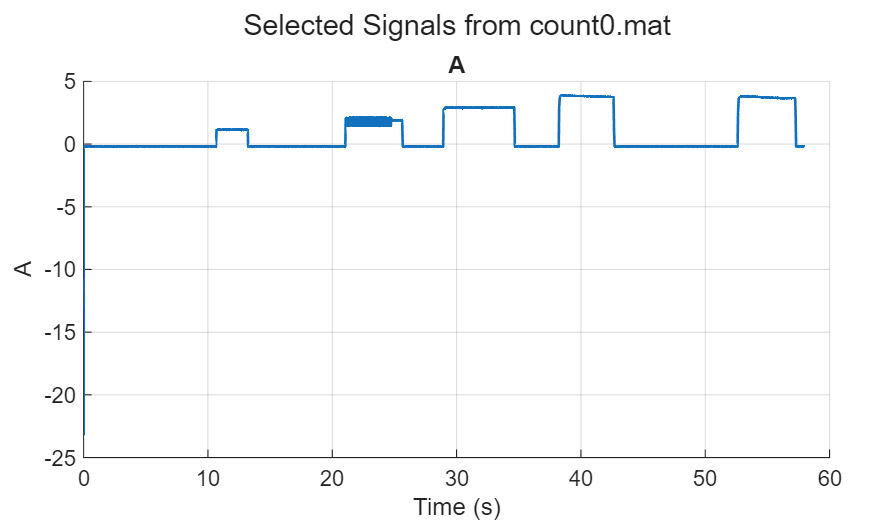

%% โปรแกรมดูกราฟจาก .mat (เลือกสัญญาณ + sync เวลา + เส้นอ่านค่า + แสดงค่าจุดตัด)
clc; clear; close all;

% 🔹 เลือกไฟล์
[filename, pathname] = uigetfile('*.mat', 'เลือกไฟล์ข้อมูล (.mat)');
if isequal(filename, 0)
    disp('ยกเลิก');
    return;
end
fullpath = fullfile(pathname, filename);
load(fullpath);

% 🔹 ค้นหา Dataset
vars = whos;
datasetName = '';
for i = 1:length(vars)
    if strcmp(vars(i).class, 'Simulink.SimulationData.Dataset')
        datasetName = vars(i).name;
        break;
    end
end
if isempty(datasetName)
    error('ไม่พบ Dataset ในไฟล์นี้');
end
data = eval(datasetName);

% 🔹 เตรียมชื่อสัญญาณ (รองรับกรณีไม่มีชื่อ)
numSignals = data.numElements;
signalNames = cell(1, numSignals);
for i = 1:numSignals
    sig = data.get(i);
    % ถ้ามีชื่อใช้ชื่อเดิม
    if ~isempty(sig.Name)
        signalNames{i} = sprintf('%d: %s', i, sig.Name);
    % ถ้าไม่มีชื่อ แต่มี BlockPath ให้ใช้ชื่อบล็อกแทน
    elseif ~isempty(sig.BlockPath)
        try
            blkName = sig.BlockPath.getBlock(1);
            signalNames{i} = sprintf('%d: [NoName] %s', i, blkName);
        catch
            signalNames{i} = sprintf('%d: [NoName]', i);
        end
    else
        % ถ้าไม่มีทั้งคู่ ตั้งชื่ออัตโนมัติ
        signalNames{i} = sprintf('%d: [Signal_%d]', i, i);
    end
end

% 🔹 เลือกสัญญาณ
[idx, tf] = listdlg('PromptString', 'เลือกสัญญาณที่ต้องการดู:', ...
                    'SelectionMode', 'multiple', ...
                    'ListString', signalNames, ...
                    'ListSize', [350 300]);
if ~tf
    disp('ยกเลิก');
    return;
end

% 🔹 สร้างกราฟ
figure('Name', ['Signal Viewer: ' filename], 'NumberTitle', 'off');
tiledlayout(length(idx), 1, 'Padding', 'compact', 'TileSpacing', 'compact');
ax = gobjects(length(idx),1);
lines = cell(length(idx),1);
texts = gobjects(length(idx),1);

for k = 1:length(idx)
    sig = data.get(idx(k));
    val = sig.Values;

    % 🔹 ตรวจสอบการมีอยู่ของฟิลด์ Time และ Data
    if ~isprop(val, 'Time') || ~isprop(val, 'Data')
        warning('ข้ามสัญญาณ %d: ไม่มีข้อมูล Time หรือ Data', k);
        continue;
    end

    t = val.Time;
    y = val.Data;

    % 🔹 ถ้าเป็นข้อมูล 3 มิติ (เช่น 1x1xN) → บีบให้เหลือ 1 มิติ
    if ndims(y) > 2
        y = squeeze(y);
    end

    % 🔹 ถ้า y กลายเป็นเมทริกซ์ (เช่น NxM) ให้ plot ทีละ column
    ax(k) = nexttile;
    hold(ax(k), 'on');
    if ismatrix(y) && size(y,2) > 1
        for c = 1:size(y,2)
            plot(ax(k), t, y(:,c), 'LineWidth', 1.2, 'DisplayName', sprintf('Col %d', c));
        end
        legend(ax(k), 'show');
    else
        plot(ax(k), t, y, 'LineWidth', 1.2);
    end

    grid(ax(k), 'on');
    xlabel(ax(k), 'Time (s)');

    % 🔹 ถ้าไม่มีชื่อ signal → ตั้งชื่ออัตโนมัติ
    if isempty(sig.Name)
        sigName = sprintf('Signal %d', idx(k));
    else
        sigName = sig.Name;
    end

    ylabel(ax(k), sigName, 'Interpreter', 'none');
    title(ax(k), sigName, 'Interpreter', 'none');

    lines{k} = findobj(ax(k), 'Type', 'Line');
    texts(k) = text(ax(k), NaN, NaN, '', 'Color', 'r', 'FontSize', 9, 'FontWeight', 'bold', ...
                    'BackgroundColor', 'w', 'Margin', 2);
    hold(ax(k), 'off');
end


sgtitle(['Selected Signals from ', filename], 'Interpreter', 'none');
linkaxes(ax, 'x');

% 🔹 สร้างเส้นแนวตั้ง
cursorLines = gobjects(length(ax), 1);
for k = 1:length(ax)
    yl = ylim(ax(k));
    cursorLines(k) = line(ax(k), [NaN NaN], yl, 'Color', 'r', 'LineStyle', '--', 'LineWidth', 1);
end

% 🔹 ตั้ง callback สำหรับการลากเส้น
set(gcf, 'WindowButtonDownFcn', @(src, event) startCursorDrag(src, ax, cursorLines, lines, texts));


disp('✅ แสดงกราฟพร้อมเส้นอ่านค่าและจุดตัดแล้ว!');

✅ แสดงกราฟพร้อมเส้นอ่านค่าและจุดตัดแล้ว!



% ==========================================================
% 🔸 ฟังก์ชันย่อย
function startCursorDrag(fig, ax, cursorLines, lines, texts)
    cp = get(ax(1), 'CurrentPoint');
    xClick = cp(1,1);
    updateCursor(xClick, ax, cursorLines, lines, texts);
    set(fig, 'WindowButtonMotionFcn', @(~,~) motionFcn(ax, cursorLines, lines, texts));
    set(fig, 'WindowButtonUpFcn', @(~,~) stopCursorDrag(fig));
end

function motionFcn(ax, cursorLines, lines, texts)
    cp = get(ax(1), 'CurrentPoint');
    xNow = cp(1,1);
    updateCursor(xNow, ax, cursorLines, lines, texts);
end

function stopCursorDrag(fig)
    set(fig, 'WindowButtonMotionFcn', '');
    set(fig, 'WindowButtonUpFcn', '');
end

function updateCursor(xPos, ax, cursorLines, lines, texts)
    for k = 1:length(ax)
        yl = ylim(ax(k));
        set(cursorLines(k), 'XData', [xPos xPos], 'YData', yl);

        t = lines{k}.XData;
        y = lines{k}.YData;
        if isempty(t) || isempty(y), continue; end

        [~, idx] = min(abs(t - xPos));
        yVal = y(idx);

        if ~isnan(yVal)
            set(texts(k), 'Position', [xPos, yVal], ...
                          'String', sprintf('t=%.3f s\ny=%.3f', t(idx), yVal));
        else
            set(texts(k), 'String', '');
        end
    end
end

